**AFSAH  HYDER**

**LAB 04**

**Activity 1**

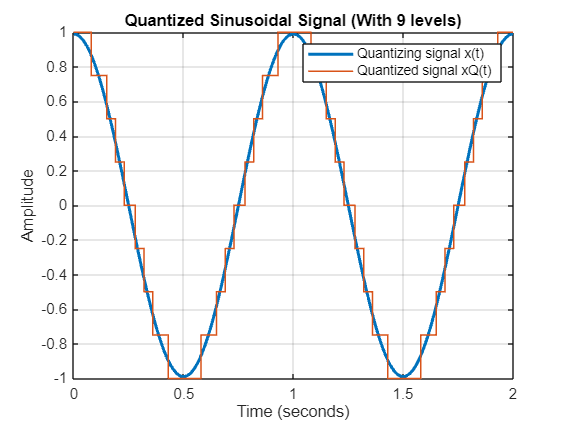

% Parameters
A = 0.99;         % Amplitude ( < R/2)
f0 = 1;           % Frequency in Hz
Ts = 0.01;       % Sampling period in seconds
B = 3;            % Number of bits for quantization
R = 2;            % Dynamic range
t = 0:Ts:2;       % Time vector (1 second duration)

% Generate continuous-time signal x(t)
xt = A * cos(2*pi*f0*t);

% Define quantization levels
num_levels = 2^B;  % Number of quantization levels
Q = R/num_levels;

% Quantize the signal
xQ_t = round(xt / Q) * Q;  % Quantized signal

% Plot the quantized signal using stairs
figure;
plot(t,xt,'LineWidth', 2); hold on;
stairs(t, xQ_t, 'LineWidth', 1); hold off;
xlabel('Time (seconds)');
ylabel('Amplitude');
title('Quantized Sinusoidal Signal (With 9 levels)');
legend("Quantizing signal x(t)", "Quantized signal xQ(t)");
grid on;

This has more levels, but it gives exactly 0 mean, when i was using 8 levels, the mean i got was not near to 0 at all.

Just to highlight this, I am showing both graphs

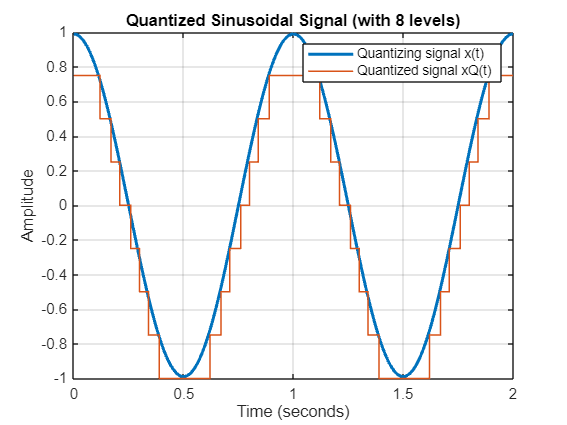

% Generate continuous-time signal x(t)
xt2 = A * cos(2*pi*f0*t);

% Quantize the signal
xQ_t2 = floor(xt / Q) * Q;  % Quantized signal

% Plot the quantized signal using stairs
figure;
plot(t,xt2,'LineWidth', 2); hold on;
stairs(t, xQ_t2, 'LineWidth', 1); hold off;
xlabel('Time (seconds)');
ylabel('Amplitude');
title('Quantized Sinusoidal Signal (with 8 levels)');
legend("Quantizing signal x(t)", "Quantized signal xQ(t)");
grid on;

**Activity 2**

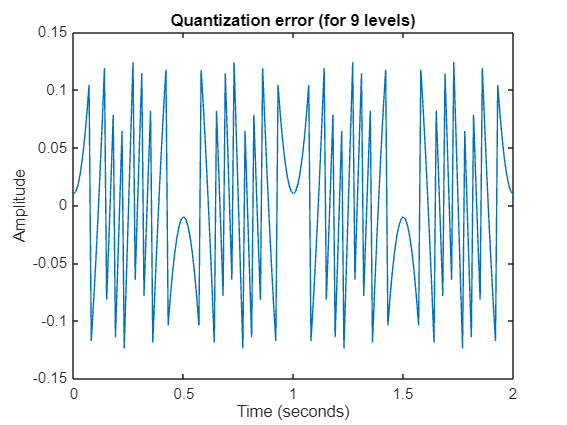

e_t = xQ_t - xt;  % Quantization error
plot(t,e_t); xlabel('Time (seconds)');
ylabel('Amplitude');
title(['Quantization error (for 9 levels)']);


mean_error = mean(e_t);
var_error = var(e_t);

fprintf('Mean of the quantization error: %.4f\n', mean_error);

Mean of the quantization error: 0.0000


fprintf('Variance of the quantization error: %.4f\n', var_error);

Variance of the quantization error: 0.0049


var_errort = Q^2/12;
fprintf('Theoretical variance of the quantization error: %.4f\n', var_errort);

Theoretical variance of the quantization error: 0.0052


for 8 levels

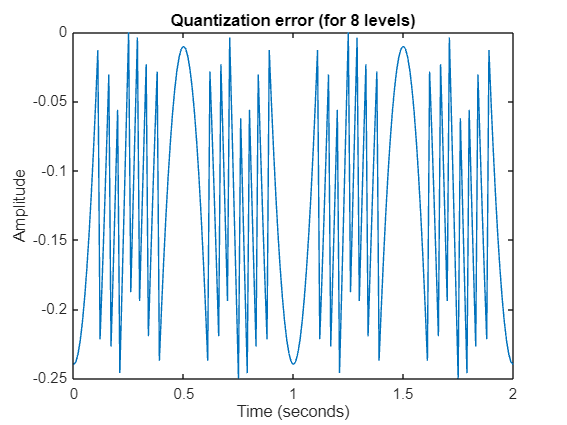

e_t = xQ_t2 - xt2;  % Quantization error
plot(t,e_t); xlabel('Time (seconds)');
ylabel('Amplitude');
title('Quantization error (for 8 levels)');


mean_error = mean(e_t);
var_error = var(e_t);

fprintf('Mean of the quantization error: %.4f\n', mean_error);

Mean of the quantization error: -0.1256


fprintf('Variance of the quantization error: %.4f\n', var_error);

Variance of the quantization error: 0.0058


var_errort = Q^2/12;
fprintf('Theoretical variance of the quantization error: %.4f\n', var_errort);

Theoretical variance of the quantization error: 0.0052


The computed mean and variance, for 9 levels, are indeed quite close to the theoretical calues in equation 4. So now we stick to 9 levels quantization for future tasks.

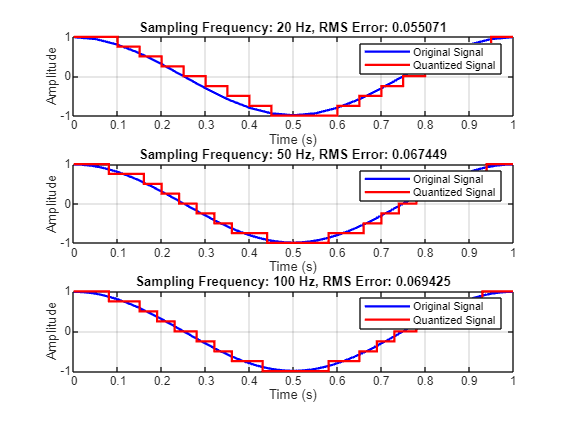

% Parameters
A = 0.99;         % Amplitude ( < R/2)
f0 = 1;           % Frequency in Hz
Ts = 0.01;       % Sampling period in seconds
B = 3;            % Number of bits for quantization
R = 2;            % Dynamic range
t = 0:Ts:2;       % Time vector (1 second duration)

% Define different sampling frequencies
sampling_freqs = [20, 50, 100]; % Samples per second
rms_errors_B = [];

figure;
hold on;
for i = 1:length(sampling_freqs)
    Ts = 1 / sampling_freqs(i); % Sampling period
    t = 0:Ts:1; % Duration from 0 to 1 second
    x = A * cos(2 * pi * f0 * t); % Original signal

    % Quantization
    xQ = Q * round(x / Q);
    error = xQ - x;

    % Calculate RMS value of error
    rms_error = sqrt(mean(error.^2));
    rms_errors_B = [rms_errors_B, rms_error];
    
    % Plot for visualization
    subplot(length(sampling_freqs), 1, i);
    plot(t, x, 'b-', 'LineWidth', 1.5);
    hold on;
    stairs(t, xQ, 'r-', 'LineWidth', 1.5);
    title(['Sampling Frequency: ', num2str(sampling_freqs(i)), ' Hz, RMS Error: ', num2str(rms_error)]);
    legend('Original Signal', 'Quantized Signal');
    xlabel('Time (s)');
    ylabel('Amplitude');
    grid on;
end
hold off;


disp('Effect of Sampling Frequency on RMS Error (Activity 2B):');

Effect of Sampling Frequency on RMS Error (Activity 2B):


disp(array2table([sampling_freqs', rms_errors_B'], 'VariableNames', {'Sampling_Frequency', 'RMS_Error'}));

    Sampling_Frequency    RMS_Error
    __________________    _________

            20            0.055071 
            50            0.067449 
           100            0.069425 



**Theoretical Analysis**

Increasing the sampling frequency means taking more samples of the signal per second. However, the quantization process is determined by the number of quantization levels, given by L=2^B, which defines the quantization step size Q=R/L�. This step size remains constant regardless of the sampling rate.

**As a result:**

- The quantization error per sample remains unchanged.

- The RMS value of the quantization error is primarily influenced by the quantization resolution (set by B) and the signal amplitude, rather than the sampling frequency.

**Practical Observations**

From the code output, we notice that the quantization error does change, contrary to our theoretical expectations. The error varies when increasing the sampling frequency from 20 to 50 but stabilizes from 50 to 100, aligning with theoretical predictions.

**Possible reasons:**

- At lower sampling frequencies, fewer samples are taken, leading to different alignments with quantization levels and slight variations in the error distribution.

- Higher sampling frequencies capture more points, allowing the sampled signal to better approximate the original waveform, thereby stabilizing the error.

- More data in the RMS calculation can either smooth out minor variations or introduce slight fluctuations.

**2c**

% Activity 2C: Effect of Quantization Bits on Quantization Error
Ts = 0.01;  %Fixed sampling period
t = 0:Ts:1; % Duration from 0 to 1 second
x = A * cos(2 * pi * f0 * t); % Original signal

quant_bits = [2, 3, 4, 5]; % Different values of B
rms_errors_C = [];

figure;
hold on;
for i = 1:length(quant_bits)
    disp('quant bits are: ')
    B = quant_bits(i)
    num_levels = 2^B;
    Q = R / num_levels;

    % Quantization
    xQ = Q * round(x /Q);
    unique(xQ)
    error = xQ - x;

    % Calculate RMS value of error
    rms_error = sqrt(mean(error.^2));
    rms_errors_C = [rms_errors_C, rms_error];
    
    % Plot for visualization
    subplot(length(quant_bits), 1, i);
    plot(t, x, 'b-', 'LineWidth', 1.5);
    hold on;
    stairs(t, xQ, 'r-', 'LineWidth', 1.5);
    title(['Quantization Bits: ', num2str(B), ', RMS Error: ', num2str(rms_error)]);
    legend('Original Signal', 'Quantized Signal');
    xlabel('Time (s)');
    ylabel('Amplitude');
    grid on;
end

quant bits are: 


B = 2

ans =    -1.0000   -0.5000         0    0.5000    1.0000


quant bits are: 


B = 3

ans =    -1.0000   -0.7500   -0.5000   -0.2500         0    0.2500    0.5000    0.7500    1.0000


quant bits are: 


B = 4

ans =    -1.0000   -0.8750   -0.7500   -0.6250   -0.5000   -0.3750   -0.2500   -0.1250         0    0.1250    0.2500    0.3750    0.5000    0.6250    0.7500    0.8750    1.0000


quant bits are: 


B = 5

ans =    -1.0000   -0.9375   -0.8750   -0.8125   -0.7500   -0.6875   -0.6250   -0.5625   -0.5000   -0.4375   -0.3750   -0.3125   -0.2500   -0.1875   -0.1250   -0.0625         0    0.0625    0.1250    0.1875    0.2500    0.3125    0.3750    0.4375    0.5000    0.5625    0.6250    0.6875    0.7500    0.8125    0.8750    0.9375    1.0000


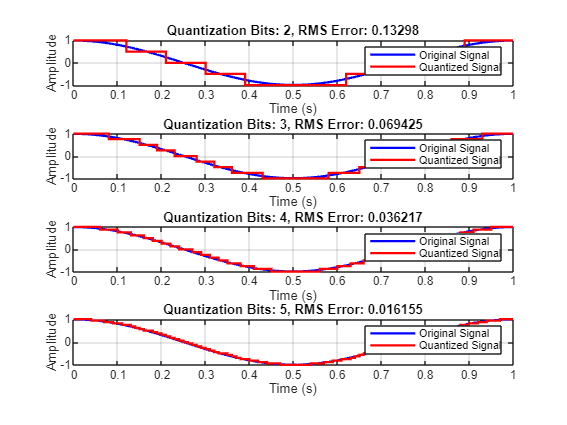

hold off;


disp('Effect of Quantization Bits on RMS Error (Activity 2C):');

Effect of Quantization Bits on RMS Error (Activity 2C):


disp(array2table([quant_bits', rms_errors_C'], 'VariableNames', {'Quantization_Bits', 'RMS_Error'}));

    Quantization_Bits    RMS_Error
    _________________    _________

            2             0.13298 
            3            0.069425 
            4            0.036217 
            5            0.016155 



**Key Observations:**

- Increasing the number of quantization bits,B, increases the number of quantization levels L, reducing the quantization step size Q.

- A smaller step size results in reduced quantization error, leading to a lower RMS error.

- As expected, the RMS error consistently decreases with increasing B, improving the signal's accuracy.

- However, increasing B requires additional storage and bandwidth to accommodate the extra data.

**Activity 3**

binary_str = '0011';  % 4-bit binary string
xQ = twosComplementToDecimal(binary_str);
disp(xQ);

    0.3750




binary_str = '1011';  % 4-bit binary string
xQ = twosComplementToDecimal(binary_str);

inverted_str_num = '101'

disp(xQ);

   -0.6250



**Activity 4**

% from values printed in activity 2
xQ = [0.75, 0.5, 0.25, 0.0, -0.25, -0.5, -0.75, -1.0];
B = 3;
activty4(xQ, B)

ans = 8×2 table
    Quantized_Value    Binary_Bits
    _______________    ___________

          0.75           {'011'}  
           0.5           {'010'}  
          0.25           {'001'}  
             0           {'000'}  
         -0.25           {'110'}  
          -0.5           {'101'}  
         -0.75           {'100'}  
            -1           {'100'}  



xQ = [0.875, 0.750, 0.625, 0.500, 0.375, 0.250, 0.125, 0, -0.125, -0.250, -0.375, -0.500, -0.625, -0.750, -0.875, -1.000];
B = 4;
activty4(xQ, B)

ans = 16×2 table
    Quantized_Value    Binary_Bits
    _______________    ___________

         0.875          {'0111'}  
          0.75          {'0110'}  
         0.625          {'0101'}  
           0.5          {'0100'}  
         0.375          {'0011'}  
          0.25          {'0010'}  
         0.125          {'0001'}  
             0          {'0000'}  
        -0.125          {'1110'}  
         -0.25          {'1101'}  
        -0.375          {'1100'}  
          -0.5          {'1011'}  
        -0.625          {'1010'}  
         -0.75          {'1001'}  
        -0.875          {'1000'}  
            -1          {'1000'}  


**Activity 5**

For R > 2:

bitpattern = decimalToTwosComplement(-3.625, 4, 4);
disp(bitpattern);

11011010



bitpattern = decimalToTwosComplement(-5.375, 4, 4);
disp(bitpattern);

10110110


**Dry Run Explanation for  the number: -5.375**

**1. Integer Part Conversion**

- The integer part is -5, which is represented in 4-bit binary as 1011.

**2. Fractional Part Conversion**

The fractional part is 0.375, converted using successive multiplications by 2:

- 0.375 × 2 = 0.750 → Record 0

- 0.75 × 2 = 1.50 → Record 1

- 0.50 × 2 = 1.0 → Record 1

- No remainder → Stop

Thus, the 4-bit representation of 0.375 is 0110

**3. Combining Integer and Fractional Parts**

Final binary representation: 10110110

**Use Cases:**

- **Embedded Systems** – Fixed-point representation is essential in microcontrollers where floating-point operations are computationally expensive.

- **Digital Signal Processing (DSP)** – Two’s complement is widely used in DSP applications for efficient audio and image processing.

- **Computer Arithmetic** – Understanding binary representations is crucial for designing efficient arithmetic circuits.

This highlights the importance of choosing the correct binary conversion function based on the number's range and format requirements. 